folder = "11_04_22/uav_data/*.csv";
files = dir(folder);
display(files)

files = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 6; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
uav_data = file.data(file.data(:,1) < 2000000, :);

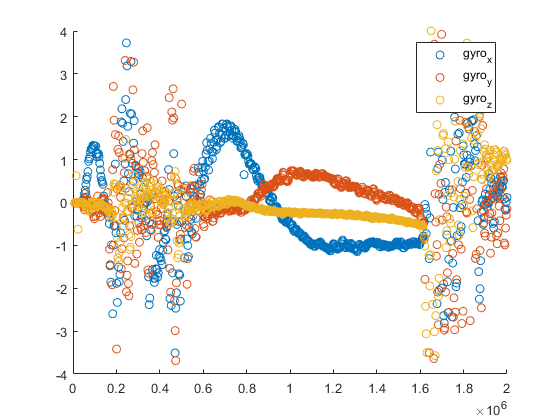

clf
hold on
ylim([-4 4])
scatter(uav_data(:,1), uav_data(:,2))
scatter(uav_data(:,1), uav_data(:,3))
scatter(uav_data(:,1), uav_data(:,4))
legend(file.colheaders(2:4))
hold off

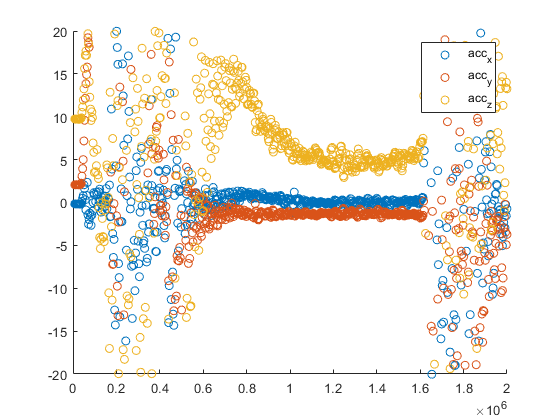

clf
hold on
ylim([-20 20])
scatter(uav_data(:,1), uav_data(:,5))
scatter(uav_data(:,1), uav_data(:,6))
scatter(uav_data(:,1), uav_data(:,7))
legend(file.colheaders(5:7))
hold off

% histogram(1000000./diff(data(:,1)), 100)

% 
% ifilt = imufilter('SampleRate', 333);
% for ii=1:size(imu_data,1)
%     qimu = ifilt(imu_data(ii,5:7), imu_data(ii,2:4));
%     set(poseplot, "Orientation", qimu)
%     drawnow limitrate
% end

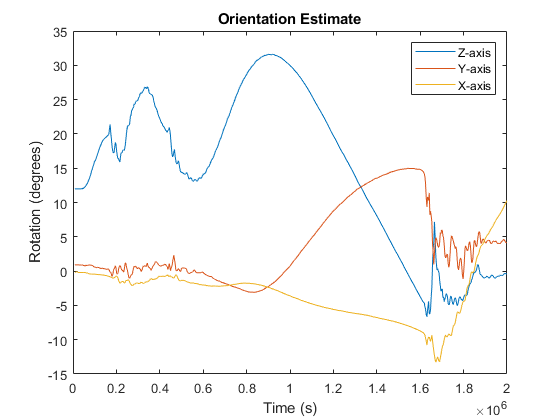

imu_data = uav_data(uav_data(:,1) > 0, :);
ifilt = imufilter('SampleRate', 333, 'LinearAccelerationDecayFactor', 0.85);
a = ifilt(imu_data(:,5:7), imu_data(:,2:4));

time_imu = (0:1:size(imu_data,1)-1)/333;
orientation = eulerd(a,'XYZ','frame');
plot(uav_data(:,1),orientation)
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

az = imu_data(:,5);
ax = imu_data(:,6);
ay = imu_data(:,7);

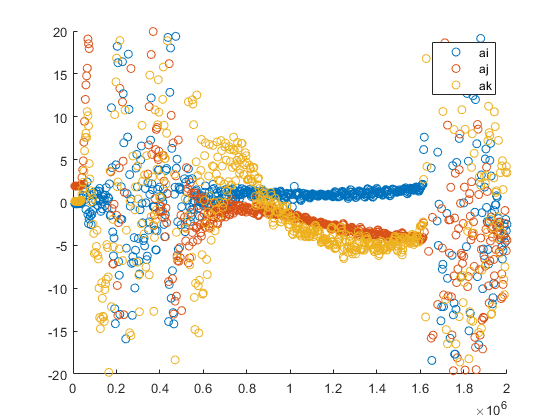

az_abs = imu_data(:,5) - (9.81 * tand(orientation(:,3)));
ax_abs = imu_data(:,6) - (9.81 * tand(orientation(:,2)));
ay_abs = imu_data(:,7) - (9.81 * cosd(orientation(:,1)));
clf
hold on
ylim([-20 20])
scatter(uav_data(:,1), az_abs, 'DisplayName', "ai")
scatter(uav_data(:,1), ax_abs, 'DisplayName', "aj")
scatter(uav_data(:,1), ay_abs, 'DisplayName', "ak")
hold off
legend

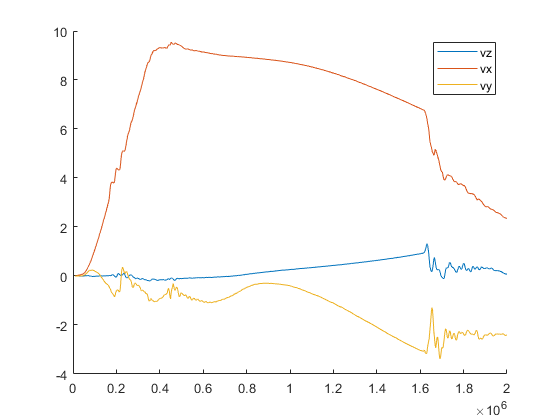

clf
vz = cumtrapz(imu_data(:,1)./1e6, az_abs);
vx = cumtrapz(imu_data(:,1)./1e6, ax_abs);
vy = cumtrapz(imu_data(:,1)./1e6, ay_abs);
hold on
plot(uav_data(:,1), vz, 'DisplayName', "vz")
plot(uav_data(:,1), vx, 'DisplayName', "vx")
plot(uav_data(:,1), vy, 'DisplayName', "vy")
hold off
legend

% clf
% v = [vz';vx';vy'];
% xlim([0,1.6])
% hold on
% mag = vecnorm(v);
% plot(uav_data(:,1)/1e6, mag, 'DisplayName', "acc")
% plot(time(time>7)-7.5, absVelocity(time>7), 'DisplayName', "qualsis")
% hold off
% legend
% xlabel("time")
% ylabel("Absolute velocity")

folder = "11_04_22/uav_data/*.csv";
files = dir(folder);
display(files)

files = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 6; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
uav_data = file.data(file.data(:,1) < 2000000, :);

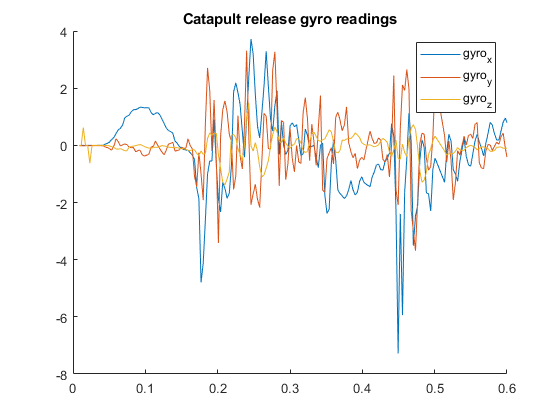

clf
hold on
title("Catapult release gyro readings")
xlim([0,0.6])
plot(uav_data(:,1)/1e6, uav_data(:,2))
plot(uav_data(:,1)/1e6, uav_data(:,3))
plot(uav_data(:,1)/1e6, uav_data(:,4))
legend(file.colheaders(2:4))
hold off

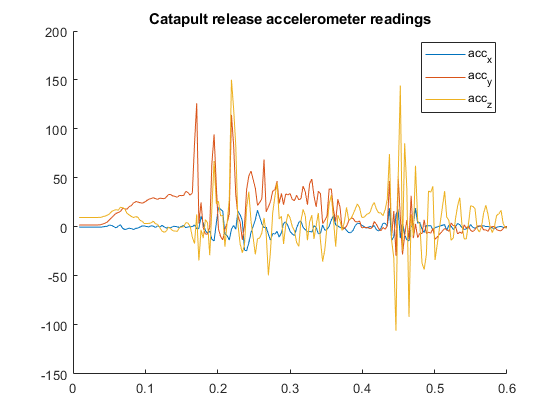

clf
hold on
title("Catapult release accelerometer readings")
xlim([0,0.6])
plot(uav_data(:,1)/1e6, uav_data(:,5))
plot(uav_data(:,1)/1e6, uav_data(:,6))
plot(uav_data(:,1)/1e6, uav_data(:,7))
legend(file.colheaders(5:7))
hold off

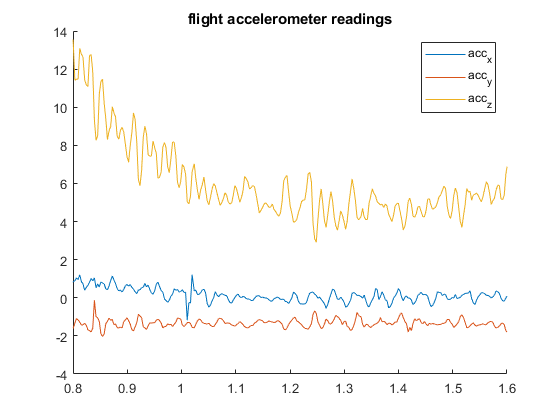

clf
hold on
title("flight accelerometer readings")
xlim([0.8,1.6])
plot(uav_data(:,1)/1e6, uav_data(:,5))
plot(uav_data(:,1)/1e6, uav_data(:,6))
plot(uav_data(:,1)/1e6, uav_data(:,7))
legend(file.colheaders(5:7))
hold off

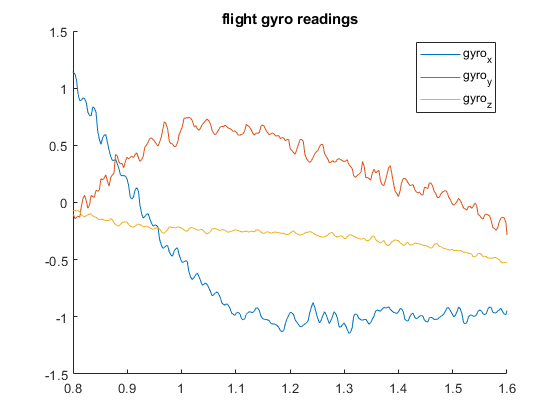

clf
hold on
title("flight gyro readings")
xlim([0.8,1.6])
plot(uav_data(:,1)/1e6, uav_data(:,2))
plot(uav_data(:,1)/1e6, uav_data(:,3))
plot(uav_data(:,1)/1e6, uav_data(:,4))
legend(file.colheaders(2:4))
hold off

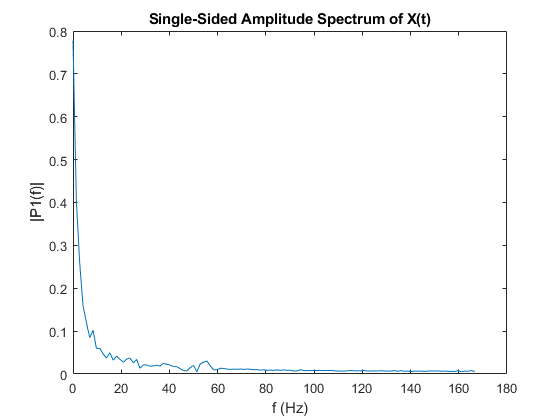

accz = uav_data(:,2);
acct = uav_data(:,1)/1e6;

accz = accz(acct < 1.58);
acct = acct(acct < 1.58);

accz = accz(acct > 0.86);
acct = acct(acct > 0.86);

Fs = 333.2;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(accz);             % Length of signal
t = (0:L-1)*T;        % Time vector

Y = fft(accz);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')